# **Code View of **

# **MK3 Capstone Project**

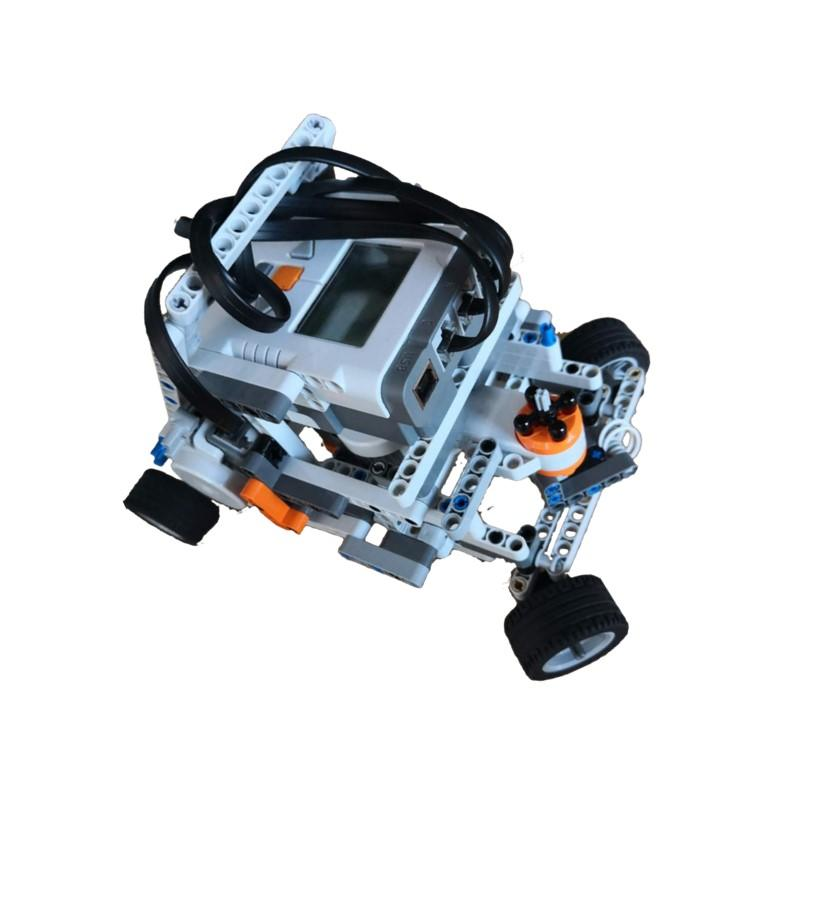

## This is the script which shows coding of MK3 capstone project, we wil siumliate the case of a driverless car, whose sensor measurement could be attacked and tampered by a cyber hacker. The sensor measurement is important for the autonomous control of the car, thus a false data will cause an unwanted car's trajectory. Our task is to show the bad result of sensor attack and develop a software demo on countering this security problem.  More detail will be illustrated in our Capstone final report.

# PART 0 - Introduction

`We will set up and test our whole project on the ``LEGO Mindstorm NXT robotic set`` and controlled by this Matlab script with some other function we created. We use the ``LEGO MindStorm NXT Toolbox ``developed by the `[`RWTH Aachen University student project - MATLAB meets LEGO Mindstorms`](http://www.mindstorms.rwth-aachen.de/) `as our development code package. `

# PART 1 - Initialization

`In this script we can use two ways to control the car, one is use preset trajectory and the other is to use a joystick. In Initialization section, we reserve the variable for the preset trajectory controlling method, where ``theta `$\theta$` represents the steering angle of the car and ``w_ref `$\omega_{\mathrm{ref}}$` represents the wanted angular velocity of the driving Motor. Since there are two driving motors being placed on each side of the car and they will have two different angular velocity when the car is not going straight in modelling the differential device of real car, thus we say the wanted velocity ``w_ref `$\omega_{\mathrm{ref}}$` applys for the`` outboard driving motor. ``A function will be defined for recognition of the innerboard driving motors.`

## Preset Trajectory

theta = 0;                                % Steering angle;
w_ref = 0;                                % Initial Steering Angle;
theta_standby = 0;                        % This variable is reserved for correcting the false data of steering motor;
Duration = 30;                            % State the total time of moving;

## Sampling Period - State Space Matrices Dictionary and Active Joystick Object

`The issue of unfixed sampling rate has been described in the report, for decreasing the complexity, we choose to calculate out all the state-space matrices for each possible sampling period and store them in a dictionary object. Thus we load the dictionary in Initialization part. More detail, right click and open the function below:`

***The function for making dictionary is called : ******''NXT_Demo_Matrix_dictionary''***                              

load('Matrices_dic.mat');                 % Load the pre-derived state space matrices;
mat = Matrices_dic;                       % Assign 'mat' as the reference matrices dictionary;    
joy = vrjoystick(1);                      % Create a JOYSTICK object for remoting the car;

## Reserve Variables for Motor PID controller

`In the report we announced that we have used the PID controller to upgrade the performance of the response of the plant. To do that, we create some variable below to be used in recursive calculation of the PID controller. The variable named ``error_sum` $\left(\sum_{\mathrm{error}} \text{ }\right)\text{ }$`represents the sum of all past error signal, used by Integral controller. ``error_Pre``(`$e_{k-1}$`) represent the previous error signal data. The block diagram`

`below illustrate the general idea of a PID controller.`

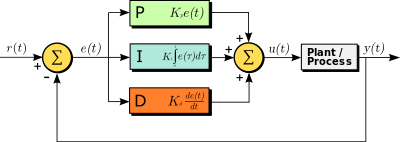

%  For Right Driving Motor;
error_sum_mA = 0;
error_Pre_mA = 0;

%  For Steering Motor;
error_sum_mB = 0;                        
error_Pre_mB = 0;                         

%  For Left Driving Motor;
error_sum_mC = 0;
error_Pre_mC = 0;

## Reserve variables for Attack Signal (software vulnerability)

`The way we represent the attack signal is just simply either set it to an fixed value or manipulate by Joystick. The attack signal will be added onto the sensor measurement, which will be notated by ``y_mea`$\left(y\left(k\right)\right)$`. The real attack signal of Cyber-Physical system attack is launched by hacker on separate platform or system and stealth to the physical system through internet, which is quite different with our setup. In the script, we launch the attack signal by ourselves but it is the same on account of attack detection or data reconstruction compared to real attck case.`

`In the script below, ``attack_data`$\left(A\left(k\right)\right)$ `is the attack signal which can very agianst time. And one of the major task is to detect the existence of the attack signal. And the ``Attack_FLAG`$\left(A_{\mathrm{FLAG}} \in R^{1\mathrm{x3}\text{ }} \right)$`, can indicate which sensor is under attack by simply chaging the corresponding bit to 1 for each sample set. And ``pre_Attack_FLAG ``just means the previous one Attack Flag set, which is used to determine at which sample the attack signal is applied. `

thre_steering = 10;               % Threshold value for steering motor.
thre_driving = 10;                % Threshold value for driving motor.


attack_data_mA = 0;                           % Constant attack for Right Driving Motor;
attack_data_mB = 0;                           % Constant attack for Steering Motor;
attack_data_mC = 0;                           % Constant attack for Left Driving Motor;
Attack_FLAG = [0 0 0];                        % Indication of Apperance of attack [mA mB mC] ;
pre_Attack_FLAG = [0 0 0];                    % previous flag of Attack_FLAG;

% The variable below are used when there is attack signal comming in, and all of them
% are represented by vector form. Each bit is corresponding to a motor in the car.
error = [0 0 0];                 % Represent the value of attack on each sensor.
benchmark = [0 0 0];             % Represent the redundancy info at the time attacker appears.    
attack_benchmark = [0 0 0];      % Represent the value of measurement at the time attacker appears
signal_change = [0 0 0];         % Represent the change of measurement at the time attacker exists

## Define State, Input, Output Vectors and Covariance Matrices for Kalman Filtering

`For simplification and accuracy, we around the state-space model of diriving motors to 1st order form, because we found to decrease the residual signal of driving motors, by reducing the order we can reduce the threshold for judging appearance of attack signal. ``The Process noise Covarianec `$P_{k\text{ }}$ `and the`` measurement noise Covariance `$R$` has been measured in advanced and given below: `

x_mB = [0; 0];                                % Steering State Vector;
y_mB = 0;                                     % Reserved for Steering Output;
y_mA = 0;                                     % Resetved for Right Driving Output;
y_mC = 0;                                     % Reserved for Left Driving Output;
Y = [y_mA, y_mB, y_mC];                       % The outpur vector;
% The unit of proess noise is normalized voltage.
% The unit of measurement noise is degree.
Pk = [5^2 0; 0 0];                            % Motor System Process noise Covariance Matrix;
R = 1;                                        % Motor System Measurement noise Covariance;

## Plotting preparaton

`The following statements define many arrays are prepared for plotting.`

`Ang_est_x`$\left(\theta {{\text{ }}_x }_{\mathrm{est}} \right)$` -------> The estimated output, made by Kalman filter;`

`Ang_mea_x`$\left(\theta {{\text{ }}_x }_{\mathrm{mea}} \right)$` -------> The sensor reading, which could be tampered; `

`Ang_real_x`$\left(\theta {{\text{ }}_x }_{\mathrm{real}} \right)$` -------> The real outpur, usually we cannot access to this value, but for demonstration,`

`                          We show the performance of detection or reconstruction by comparison with this value.`

`Ang_ref_x`$\left(\theta {\text{ }}_{{X_{\text{ }} }_{\mathrm{ref}} } \right)$--------------`> The reference value, showing the desired trajectory that each motor should follow.`

i = 1;                                        % ith Sample indicatior;
estimate_length = Duration / 0.01;            % Preestimate the length of simulation time;

% For Steering Motor;
Ang_est_mB = zeros(1, estimate_length);       % Output angle amended by last measurement;
Ang_mea_mB = zeros(1, estimate_length);       % Output angle Measured By Sensor;
Ang_real_mB = zeros(1, estimate_length);      % To record the real Motor Angle;
Steering_ref = zeros(1, estimate_length);

% For Right Driving Motor; 
omega_mA = 0;                                % Initialzie angular velocity;
Ang_est_mA = zeros(1, estimate_length);      % Output angle amended by last measurement;
Ang_mea_mA = zeros(1, estimate_length);      % Output angle Measured By Sensor;
Ang_real_mA = zeros(1, estimate_length);     % To record the real Motor Angle;

% For Left Driving Motor;
omega_mC = 0;                                % Initialzie angular velocity;
Ang_est_mC = zeros(1, estimate_length);      % Output angle amended by last measurement;
Ang_mea_mC = zeros(1, estimate_length);      % Output angle Measured By Sensor;
Ang_real_mC = zeros(1, estimate_length);     % To record the real Motor Angle;

Time_axis = zeros(1, estimate_length);       % For plotting;
Sampling_record = zeros(1, estimate_length); % To save sampling period of each sample. ;
mA_total = zeros(1, estimate_length);
mC_total = zeros(1, estimate_length);

## Deviation between measurement and estimation

`The`` dell_x`` value, which is also the ``residual`` or`` innovation ``signal `$\left(\delta {\text{ }}_X \text{ }\left(k\right)\right)$`, the key information in each sample loop that we use to predict whether the system is under attack or not.`

dell_mB = zeros(1, estimate_length);      % Difference for Steering Motor between pre-estimate and measured value ;
dell_mA = zeros(1, estimate_length);      % Difference for Right Driving Motor between pre-estimate and measured value;
dell_mC = zeros(1, estimate_length);      % Difference for Left Driving Motor between pre-estimate and measured value;

## Initial Motor Input 

`We Assume the car start with zero state and input.`

mB.ResetPosition;                         % Reset the position of Motor;
mB.Power = 0;
mA.ResetPosition;                         % Reset the position of Motor;
mA.Power = 0;
mC.ResetPosition;                         % Reset the position of Motor;
mC.Power = 0;
u_mB = 0;
u_mA = 0;
u_mC = 0;

## Store 3 previous measurements for Smoothing the Estimation

`Each iteration, we store the output vector as well as the output vector of previous threee output, thus we can use design moving average filter to smooth the estimation to decrease the threshold set for attack detection.`

pre_y = [0 0 0];
pre_2y = [0 0 0];
pre_3y = [0 0 0];

# Part 2 - Start Navigation.

## Navigation Start

`This is where we formally finish the initilization & start to make our car move.`

t_last_sample = 0;                        % We store the time ponint of last sample, help with computing sampling period.
tic;                                      % Record the time of Start;
while true

## Check the Running Time

`Once it is over the navigation duration we set, terminate the iteration.`

    t_end = toc;
    if t_end >= Duration
        break;               
    end

Joystick Control

`This part define how to use joystick to control the behaviour of car.`

`Max steering angle `$\theta {\text{ }}_{\mathrm{Ref}} =\pm 70\text{ }\mathrm{degree}$

`Max Driving Motor Angular Velocity `$\omega {\text{ }}_{\mathrm{Ref}\text{ }} =\pm 700$ degree/s

`TO Switch between preset trajectory & Joystick Control, Comment or Decomment out the following two line.`

    %     theta = -70 * axis(joy, 1);
    %     w_ref = -700 * axis(joy, 5);
    Steering_ref(i) = theta;                    % Record the Reference Steering Angle for this iteration.

## Assign Reference Angular Velocity to Motor A and Motor C (Two Driving Motor)

`In this part of each iteration, we call the function 'NXT_Demo_driving_speed_calculator' (Defined in another MATLAB file)`

`To assign two referece angluar velocity to two driving Motors, the function need reference steering angle and the outboard angluar velocity.`

    if theta == 0
        wA_ref = w_ref;
        wC_ref = w_ref;
    elseif theta < 0
        [wA_ref, wC_ref] = NXT_Demo_driving_speed_calculator(theta, w_ref);
    else
        [wC_ref, wA_ref] = NXT_Demo_driving_speed_calculator(theta, w_ref);
    end

## Sensor Reading

`In each iteration, we retrieve the measurement of each sensor. And save the time of finishing sampling.`

    y_real_mB = mB.ReadFromNXT.Position();% The real value of steering sensor reading;
    y_real_mA = mA.ReadFromNXT.Position();% The real value of Right Seneor reading;
    y_real_mC = mC.ReadFromNXT.Position();% The real value of Left Sensor reading;
    t_sample = toc;                       % Time of a sampling;
    delta_t = round(t_sample - t_last_sample, 5); % Compute the Sampling period for discretization.

## Active Steering Sensor Attack

`The following lines of this part show how to use Joystick to control the false data injection. The attack signal can be manipulated by simpling changing the attack data value or use other way to define.`

% Steering attack   
    if button(joy,6)                      % Press button to launch attack
        attack_data_mB = 20 ;             % 20 degree false data injection
    elseif button(joy,5)
        attack_data_mB = 40;              % 40 degree false data injection 
    else
        attack_data_mB = 0;
    end
% Driving attack    
    if button(joy,1)
        attack_data_mA = 200;             % e.g 200 degree false data injection
    else
        attack_data_mA = 0;
    end
    
    if button(joy,4)
        attack_data_mC = 200;
    else
        attack_data_mC = 0;
    end

## Arrange the measurement Matrix and run Kalman estimation;

    y_mea = [y_real_mA + attack_data_mA, y_real_mB + attack_data_mB, y_real_mC + attack_data_mC]; % attack signal add measurement.
    y_mea_fake = y_mea;                 % We save a attacked version of measurement for comparison.

## Get System Matrix by refering to the dictionary of state space model;

`We use a controllable canonical form to represent our model, where B & D matrices can be confirmed fixed.`

`Thus we only need to find the A and C martices.`

    sys_var = mat(char(string(delta_t)));
    A = cell2mat(sys_var(1));
    C = cell2mat(sys_var(3));

## Update New state and Output;

`After new measurement being collected, we should also recursively have a corresponding estimation, this is part of the `

`Kalman Filtering. `

`Note: 8.525 is the proportion between angular velocity and input voltage. We simplify the model for driving motor to 1st oder form.`

`Thus we actually didn't write them in state space form, but the thinking of Kalman filter still applyes.`

    x_mB = A * x_mB + [1;0] * u_mB;                                               % Estimate the state of steering motor
    Y(1) = 8.525 * u_mA * delta_t +  pre_y(1);                                    % Estimate the output of driving motor
    Y(2) = 0.7 * C * x_mB + 0.1 *  pre_y(2) + 0.1 * pre_2y(2) +  0.1 * pre_3y(2); % Estimate the output of steering motor
    Y(3) = 8.525 * u_mC * delta_t +  pre_y(3);
    residual = y_mea - Y;      % Compare the estimation and measurement.

## Estimate the Attack value by Least Mean Square algorithm

`To find out the amplitude of attack signal is an important part of attack detectin. However, because the influence of noise and instabiltiy of estimation. We cannot very accuratly compute them, an better way is to use the ``LMS algorithm``,` `which can be used to estimate a parameters in converged form. ``'mue'`` is the ``step size`` of LMS estimation, it can be adjusted by intuition.`

    mue = 0.5;
    error(1) = error(1) + 2 * mue * (residual(1) - error(1));
    error(2) = error(2) + 2 * mue * (residual(2) - error(2));
    error(3) = error(3) + 2 * mue * (residual(3) - error(3));
    dell_mA(i) = error(1);
    dell_mB(i) = error(2);
    dell_mC(i) = error(3);

## LMS Algorithm on deriving the real-time Angular velocity of Driving Motors;

`Again, using LMS algorithm, we can find out the current Angluar velocity very fast since the samping rate is quite high. Remark that the Angluar Velocity measured is not trustable once a driving motor attack is detected. This part can be considered as a pair of redundancy information with the respect of steering attack.`

    if i == 1 || i == 2
        omega_mA = omega_mA + 2 * 0.5 * ((y_mea(1) - pre_3y(1)) / delta_t);
        omega_mC = omega_mC + 2 * 0.5 * ((y_mea(3) - pre_3y(3)) / delta_t);
    else
        omega_mA = omega_mA + 2 * 0.1 * ((y_mea(1) - pre_3y(1)) / (delta_t + Sampling_record(i - 1)+ Sampling_record(i - 2)) - omega_mA);
        omega_mC = omega_mC + 2 * 0.1 * ((y_mea(3) - pre_3y(3)) / (delta_t + Sampling_record(i - 1)+ Sampling_record(i - 2)) - omega_mC);
    end

## Redundancy Information

`'theta_standby`$\left(\theta {\text{ }}_{\mathrm{standby}} \right)$`' is considered as a redundancy of Steering motor's sensor. At steady state of the close-loop control, we have:`


$$\theta {\text{ }}_{\mathrm{steering}} =\theta {\text{ }}_{\mathrm{Standby}}$$


`The equation stand for the time when there is no attack signal.`

    theta_standby = theta_standby +  2 * 0.5 * (NXT_Demo_Steering_Corrector(omega_mA, omega_mC) - theta_standby);

`Driving Motors could also be attacked, thus we also need to have a redundancy infor of each driving motor, which are given by:`

`Note: right motor is named motor A and left motor is named motor C. The function 'NXT_Demo_Driving_Corrector' is acuually a function defined for calculating redundancy information.`

    right_standby = NXT_Demo_DrivingA_Corrector(theta, omega_mC);
    left_standby = NXT_Demo_DrivingC_Corrector(theta, omega_mA);

## Sensor Attack detection

`Residual signal represent the deviation between estimation & Sensor measurement. The detection method is plain. Just by comparing the residual signal with the pre-estimated threshold value. The method of estimating threshold is to repeatly do the navigation test and find the value of maximum residual under attackless condition.`

- `Detection of Right Driving Motor Attack and preparetion for data reconstruction.`

    if residual(1) > thre_driving
        Attack_FLAG(1) = 1;
        if pre_Attack_FLAG(1) == 0
            attack_benchmark(1) = y_mea(1);
            benchmark(1) = right_standby;
        end
    else
        Attack_FLAG(1) = 0;
    end
    
    if residual(3) > thre_driving
        Attack_FLAG(3) = 1;
        if pre_Attack_FLAG(3) == 0
            attack_benchmark(3) = y_mea(3);
            benchmark(3) = left_standby;
        end
    else
        Attack_FLAG(3) = 0;
    end

- `Detection of Steering Motor Attack.`

    if abs(residual(2)) > thre_steering
       Attack_FLAG(2) = 1;
       if pre_Attack_FLAG(2) == 0 
          attack_benchmark(2) = y_mea(2);
          benchmark(2) = theta_standby;
       end
    else 
        Attack_FLAG(2) = 0;
    end

## Data Reconstruction

The data reconstruction method is cleared in the capstone report.

    if Attack_FLAG(1)
       signal_change(1) = y_mea(1) - attack_benchmark(1);
       y_mea(1) = benchmark(1) + signal_change(1);
       residual(1) = y_mea(1) - Y(1);
       if abs(residual(1)) > thre_steering
          attack_benchmark(1) = y_mea(1);
          benchmark(1) = Y(1);
          y_mea(1) = Y(1);
          residual(1) = y_mea(1) - Y(1);
       end
    end
    
    if Attack_FLAG(2)
       signal_change(2) = y_mea(2) - attack_benchmark(2);
       y_mea(2) = benchmark(2) + signal_change(2);
       residual(2) = y_mea(2) - Y(2);
       if abs(residual(2)) > thre_steering
          attack_benchmark(2) = y_mea(2);
          benchmark(2) = Y(2);
          y_mea(2) = Y(2);
          residual(2) = y_mea(2) - Y(2);
       end
    end
    
    if Attack_FLAG(3)
       signal_change(3) = y_mea(3) - attack_benchmark(3);
       y_mea(3) = benchmark(3) + signal_change(3);
       residual(3) = y_mea(3) - Y(3);
       if abs(residual(3)) > thre_steering
          attack_benchmark(3) = y_mea(3);
          benchmark(2) = Y(3);
          y_mea(3) = Y(3);
          residual(3) = y_mea(3) - Y(3);
       end
    end    
    pre_Attack_FLAG = Attack_FLAG;

## Update the Kalman estimatior;

`The finish of Kalman filtering of an iteration is placed after data reconstruction. In this part we will update the process noise Covariance Matrix and Smoothing filter.`

    K = Pk * C' / (C * Pk * C' + R);
    x_mB = x_mB + K * residual(2);        % Update the new state of Steering Motor.
    Pk = A * Pk * A + [25 0; 0 0] - K * C * Pk * C' * K';
    pre_3y = pre_2y;
    pre_2y = pre_y;
    pre_y = y_mea;

## Proceed to PID Control;

`We create a function 'NXT_Demo_PID' as PID controller, the pricinple is quite easy to understand, and the gain for P, I and D controller is adjuested to make three motors have proper response.`

    if i == 1
        mA_total(i) = mA_total(i) + wA_ref * delta_t;
        mC_total(i) = mC_total(i) + wC_ref * delta_t;
    else
        mA_total(i) = mA_total(i-1) + wA_ref * delta_t;
        mC_total(i) = mC_total(i-1) + wC_ref * delta_t;
    end
    
    [u_mB, error_Pre_mB, error_sum_mB] = NXT_Demo_PID(1, 0.02 , 0.4, theta, y_mea(2), error_Pre_mB, error_sum_mB);
    [u_mA, error_Pre_mA, error_sum_mA] = NXT_Demo_PID(1, 0, 0.3, mA_total(i), y_mea(1), error_Pre_mA, error_sum_mA);
    [u_mC, error_Pre_mC, error_sum_mC] = NXT_Demo_PID(1, 0, 0.3, mC_total(i), y_mea(3), error_Pre_mC, error_sum_mC);

    % Send the Command from controller to Plant   
    mB.Power = u_mB;
    mA.Power = u_mA;
    mC.Power = u_mC;                    
    mB.SendToNXT;
    mA.SendToNXT;
    mC.SendToNXT;

## Update the trajectories Information

`Update the arrays for plotting.`

    Ang_est_mB(i) = Y(2);
    Ang_est_mA(i) = Y(1);
    Ang_est_mC(i) = Y(3);
    Ang_mea_mB(i) = y_mea_fake(2);
    Ang_mea_mA(i) = y_mea_fake(1);
    Ang_mea_mC(i) = y_mea_fake(3);
    Ang_real_mB(i) = y_real_mB;
    Ang_real_mA(i) = y_real_mA;
    Ang_real_mC(i) = y_real_mC;

## Update time axis

    Sampling_record(i) = delta_t;
    Time_axis(i) = t_sample;
    t_last_sample = t_sample;
    i = i + 1;                             
end

## Truncate the zeros part of all plotting components

mA_total = mA_total(1:i-1);
mC_total = mC_total(1:i-1);
Steering_ref = Steering_ref(1: i -1);
Ang_est_mB = Ang_est_mB(1: i-1);
Ang_mea_mB = Ang_mea_mB(1: i-1);
Ang_real_mB = Ang_real_mB(1: i-1);
Ang_est_mA = Ang_est_mA(1: i-1);
Ang_mea_mA = Ang_mea_mA(1: i-1);
Ang_real_mA = Ang_real_mA(1: i-1);
Ang_est_mC = Ang_est_mC(1: i-1);
Ang_mea_mC = Ang_mea_mC(1: i-1);
Ang_real_mC = Ang_real_mC(1: i-1);
dell_mB = dell_mB(1: i-1);
dell_mA = dell_mA(1: i-1);
dell_mC = dell_mC(1: i-1);
Sampling_record = Sampling_record(1: i-1);
Time_axis = Time_axis(1: i-1);

# Part 3 - Plotting and Conclusion

## Recover the initial position of Steering Angle and Close All Motor

mB.Stop;
mA.Stop;
mC.Stop;
mB_reset = 0 - mB.ReadFromNXT.Position();
mB.TachoLimit = abs(mB_reset);
mB.Power = sign(mB_reset) * 20;
mB.SendToNXT;
pause(1.5);
mB.TachoLimit = 0;
close all;

## **Plooting**

t = Time_axis;
subplot(2,1,1);
plot(t,Ang_est_mB,t,Ang_mea_mB,t,Ang_real_mB, t,Steering_ref);
grid;
xlabel('Time(sec)');
ylabel('Position(Degree)');
legend('Est','Mea','Real','Reference');
subplot(2,1,2);
plot(t,dell_mB);
grid;
xlabel('Time(sec)');
ylabel('Angle(Degree)');
figure();
subplot(2,1,1);
plot(t,Ang_est_mA,t,Ang_mea_mA,t,Ang_real_mA);
grid;
xlabel('Time(sec)');
ylabel('Angle(Degree)');
legend('est','mea','real');
subplot(2,1,2);
plot(t, dell_mA);
grid;
xlabel('Time(sec)');
ylabel('Angle(Degree)');
figure();
subplot(2,1,1);
plot(t,Ang_est_mC,t,Ang_mea_mC,t,Ang_real_mC);
grid;
xlabel('Time(sec)');
ylabel('Position(Degree)');
legend('est','mea','real');
subplot(2,1,2);
plot(t, dell_mC);
grid;
xlabel('Time(sec)');
ylabel('Angle(Degree)');
toc
